% (exp(x)+y+sin(y))*dx+(exp(y)+x+x*cos(y))*dy

clear
% 1)
% y'=-(exp(x)+y+sin(y))/(exp(y)+x+x*cos(y))
syms x y(x) C
eqn=diff(y(x))==-(exp(x)+y+sin(y))/(exp(y)+x+x*cos(y))

$$eqn(x) = \frac{\partial }{\partial x}y\left(x\right)=-\frac{\sin\left(y\left(x\right)\right)+{\mathrm{e}}^{x}+y\left(x\right)}{x+{\mathrm{e}}^{y\left(x\right)}+x\,\cos\left(y\left(x\right)\right)}$$

ySol=dsolve(eqn)

$$ySol = \mathrm{solve}\left(C_{26}+{\mathrm{e}}^{x}+{\mathrm{e}}^{y}+x\,\left(y+\sin\left(y\right)\right),y\right)$$

% solve(exp(y) + x*(y + sin(y)) == - C11 - exp(x), y)
% exp(y) + x*(y + sin(y)) == - C11 - exp(x)
eq1 = exp(x) + x*y + x*sin(y) + exp(y) == C

$$eq1(x) = {\mathrm{e}}^{y\left(x\right)}+{\mathrm{e}}^{x}+x\,\sin\left(y\left(x\right)\right)+x\,y\left(x\right)=C$$

% 2)
syms x y dx dy
eq1=(exp(x)+y+sin(y))*dx+(exp(y)+x+x*cos(y))*dy

$$eq1 = \mathrm{dy}\,\left(x+{\mathrm{e}}^{y}+x\,\cos\left(y\right)\right)+\mathrm{dx}\,\left(y+{\mathrm{e}}^{x}+\sin\left(y\right)\right)$$

cfs=coeffs(eq1,[dy dx])

$$cfs = \left(\begin{array}{cc} y+{\mathrm{e}}^{x}+\sin\left(y\right) & x+{\mathrm{e}}^{y}+x\,\cos\left(y\right) \end{array}\right)$$

P=cfs(1), Q=cfs(2)

$$P = y+{\mathrm{e}}^{x}+\sin\left(y\right)$$

$$Q = x+{\mathrm{e}}^{y}+x\,\cos\left(y\right)$$

f=simplify(diff(Q,x)-diff(P,y))

$$f = 0$$

% dPy==dQx

% U(x,y)
% dUx=P, dUy=Q
syms C(y)
U=int(P,x)+C(y)

$$U = C\left(y\right)+{\mathrm{e}}^{x}+x\,\left(y+\sin\left(y\right)\right)$$

% C(y) + exp(x) + x*(y + sin(y))
simplify(diff(U,y)-Q)

$$ans = \frac{\partial }{\partial y}C\left(y\right)-{\mathrm{e}}^{y}$$

% diff(C(y), y) + x*(cos(y) + 1) == exp(y)+x+x*cos(y) => 
% dCy=exp(y) =>
C1(y)=int(exp(y),y)

$$C1(y) = {\mathrm{e}}^{y}$$

U=subs(U,C,C1)

$$U = {\mathrm{e}}^{x}+{\mathrm{e}}^{y}+x\,\left(y+\sin\left(y\right)\right)$$

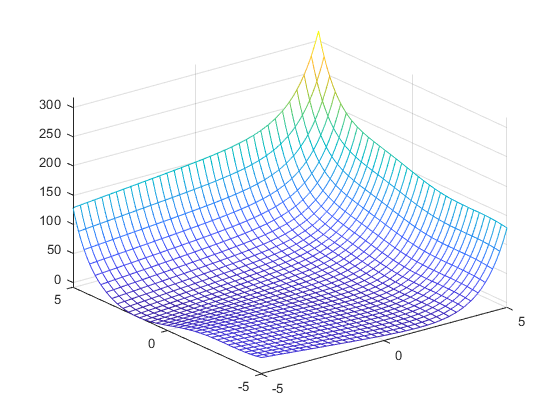

% exp(x) + x*y + x*sin(y)+exp(y) = C
fmesh(U)


% 3)
x0=0; y0=0;
U=simplify(int(P,x,x0,x)+int(subs(Q,x,x0),y,y0,y))

$$U = {\mathrm{e}}^{x}+{\mathrm{e}}^{y}+x\,y+x\,\sin\left(y\right)-2$$

syms C
eq2=U+2==C

$$eq2 = {\mathrm{e}}^{x}+{\mathrm{e}}^{y}+x\,y+x\,\sin\left(y\right)=C$$